# Import Network from PyTorch and Classify Image

Import a pretrained and traced PyTorch model as an uninitialized `dlnetwork` object to classify an image.

This example imports the MNASNet PyTorch model. MNASNet is an image classification model that is trained with images from the ImageNet database. Download the `mnasnet1_0` file, which is approximately 17 MB in size, from the MathWorks website.

modelfile = matlab.internal.examples.downloadSupportFile("nnet", ...
    "data/PyTorchModels/mnasnet1_0.pt");

Import the MNASNet model by using the `importNetworkFromPyTorch` function. The function imports the model as an uninitialized `dlnetwork` object.

net = importNetworkFromPyTorch(modelfile)

net =   dlnetwork with properties:

         Layers: [152x1 nnet.cnn.layer.Layer]
    Connections: [161x2 table]
     Learnables: [210x3 table]
          State: [104x3 table]
     InputNames: {'TopLevelModule_layers_0'}
    OutputNames: {'aten__linear12'}
    Initialized: 0

  View summary with summary.


Specify the input size of the imported network and create an image input layer. Then, add the image input layer to the imported network and initialize the network by using the `addInputLayer` function.

InputSize = [224 224 3];
inputLayer = imageInputLayer(InputSize,Normalization="none");
net = addInputLayer(net,inputLayer,Initialize=true);

Read the image you want to classify.

Im = imread("peppers.png");

Resize the image to the input size of the network. Show the image.

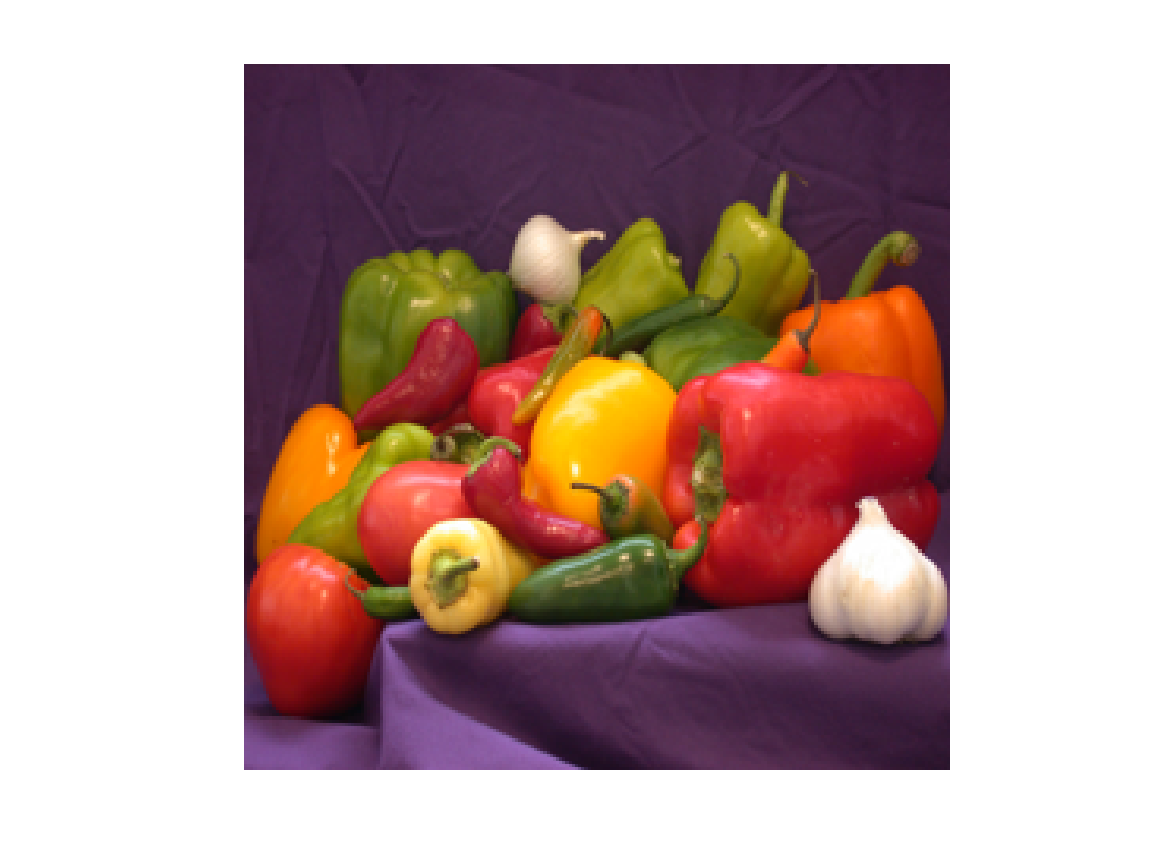

InputSize = [224 224 3];
Im = imresize(Im,InputSize(1:2));
imshow(Im)

The inputs to MNASNet require further preprocessing. Rescale the image. Then, normalize the image by subtracting the training images mean and dividing by the training images standard deviation. For more information, see [Input Data Preprocessing](docid:nnet_ug#mw_7d593336-5595-49a0-9bc0-184ba6cebb80).

Im = rescale(Im,0,1);

meanIm = [0.485 0.456 0.406];
stdIm = [0.229 0.224 0.225];
Im = (Im - reshape(meanIm,[1 1 3]))./reshape(stdIm,[1 1 3]);

Convert the image to a [`dlarray`](docid:nnet_ref#mw_bc7bf07e-0207-40d7-8568-5bdd002c6390) object. Format the image with the dimensions `"SSCB"` (spatial, spatial, channel, batch).

Im_dlarray = dlarray(single(Im),"SSCB");

Get the class names from `squeezenet`, which is also trained with ImageNet images.

squeezeNet = squeezenet;
ClassNames = squeezeNet.Layers(end).Classes;

Classify the image and find the predicted label.

prob = predict(net,Im_dlarray);
[~,label_ind] = max(prob);

Display the classification result.

ClassNames(label_ind)

ans = categorical
     bell pepper 
